%load data
load("testFeatures.mat");
test_labels = emg.epochlabelscat';

%test with simple algorithm and 1 feature
features1 = [emg_aac(1:2, :); emg_abs_mean(1:2, :); emg_kurt(1:2,:); emg_mean(1:2,:)]';

testAlg1 = fitcecoc(features1, ...
    test_labels);
% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart1 = cvpartition(test_labels,'KFold',kval); % k-fold stratified cross validation
partitionedModel1 = crossval(testAlg1,'CVPartition',cpart1);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions1, validationScores1] = kfoldPredict(partitionedModel1);
     
% Cross validation output
validationAccuracy1 = sum(validationPredictions1==test_labels)./length(test_labels);

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy1*100);


Validation accuracy = 80.56%


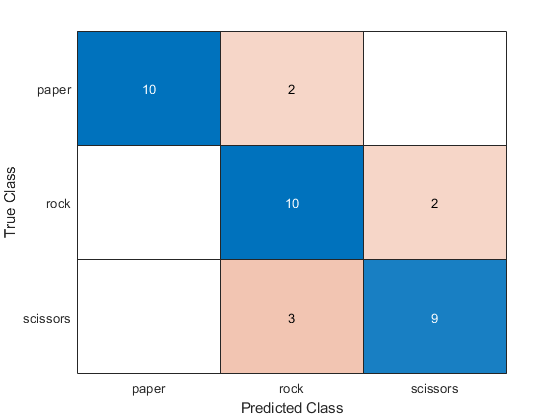

confusion_mat1 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties



confusion_mat1 = confusionchart(test_labels, validationPredictions1)

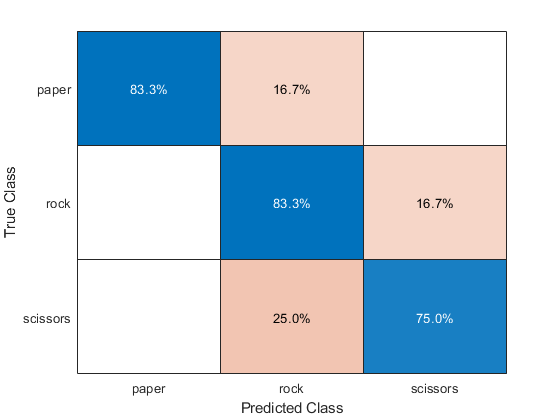

confusion_mat_norm1 =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  Show all properties


confusion_mat_norm1 = confusionchart(test_labels, validationPredictions1, 'Normalization','row-normalized')